# Tutorial: Filtering

by: ardimas (ardimasandipurwita@outlook.com)

19 Aug 2019

clear

addpath('./../lib/filter')
addpath('./../lib/misc')
addpath('./../lib/simulator')
addpath('./../lib/tgbb')
addpath('./../data/freqresponse')

## Choose Filters

### Tx and Rx AFEs

The frontend models of TGbb are detailed on [https://mentor.ieee.org/802.11/dcn/18/11-18-1574-05-00bb-lc-frontend-models.pptx.](https://mentor.ieee.org/802.11/dcn/18/11-18-1574-05-00bb-lc-frontend-models.pptx.) They exhibit a bandpass characteristic.

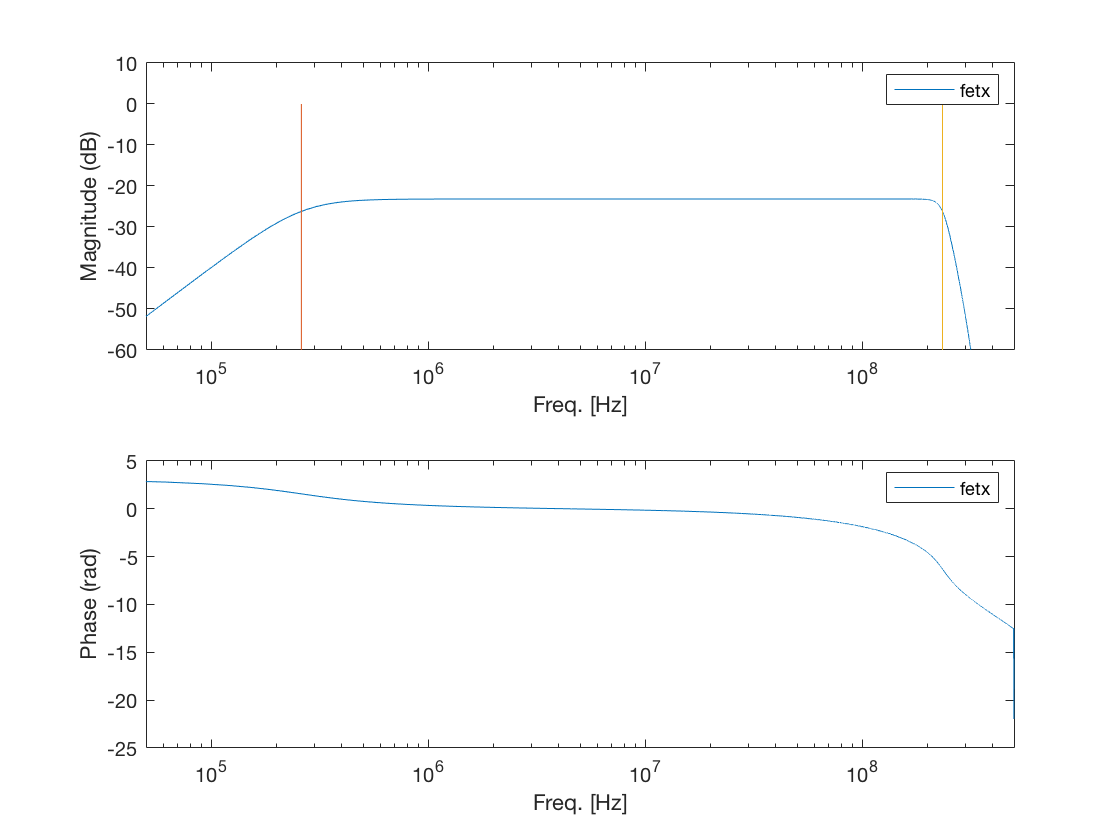

fetx = choose_filter('fetx','verbose',true);

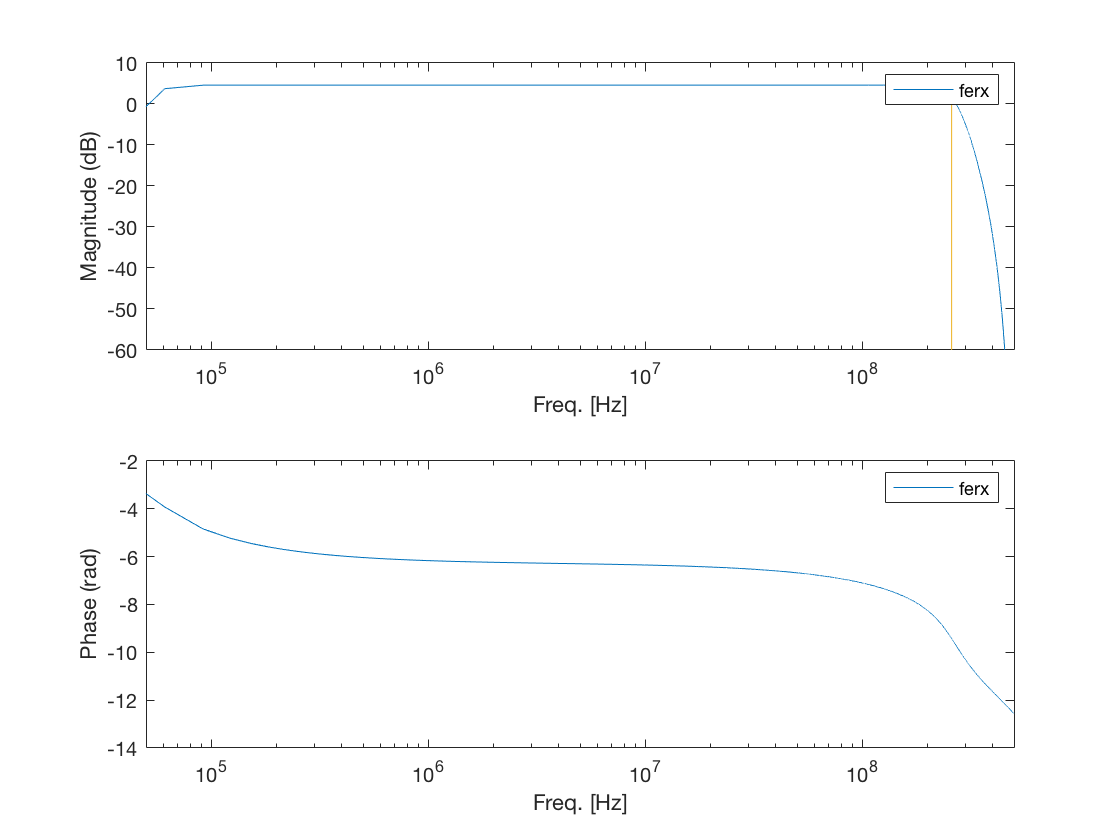

ferx = choose_filter('ferx','verbose',true);

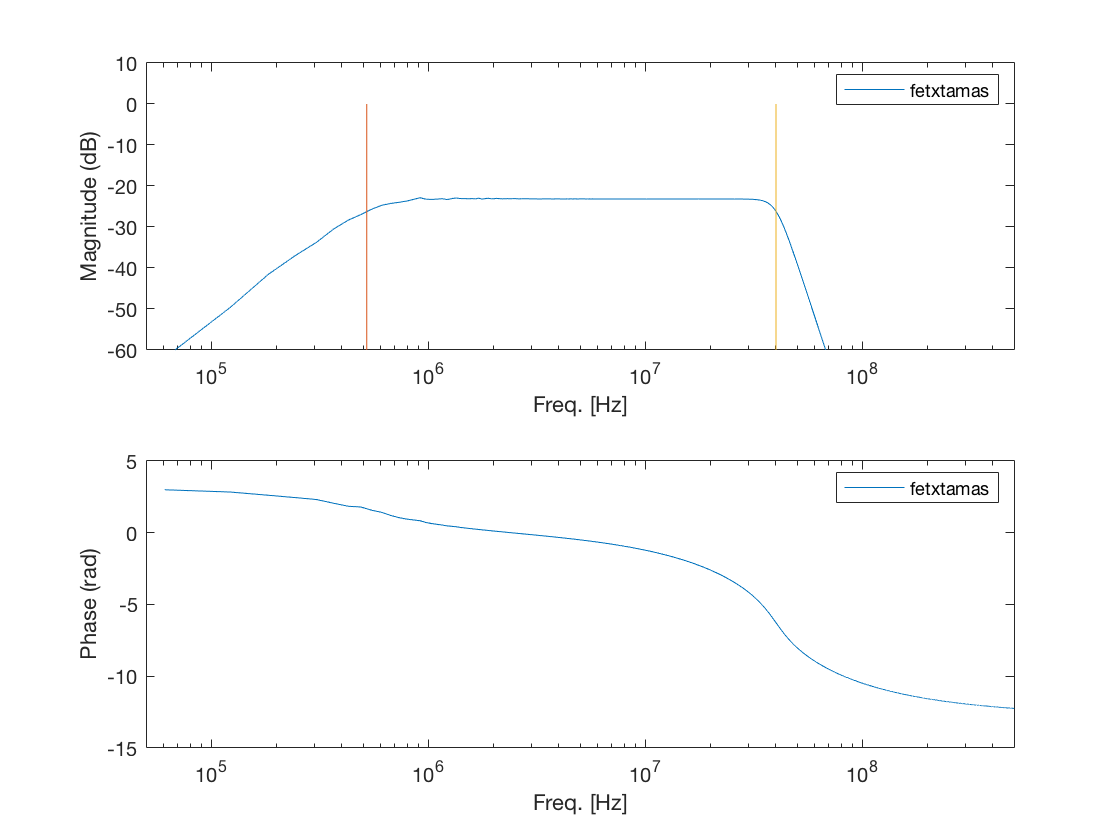

fetxtamas = choose_filter('fetxtamas','verbose',true);

ferxtamas = choose_filter('fetxtamas','verbose',true);

### CIRs

Descriptions of CIRs of TGbb are detailed on [https://mentor.ieee.org/802.11/dcn/18/11-18-1582-04-00bb-ieee-802-11bb-reference-channel-models-for-indoor-environments.pdf.](https://mentor.ieee.org/802.11/dcn/18/11-18-1582-04-00bb-ieee-802-11bb-reference-channel-models-for-indoor-environments.pdf.) The CIRs are generated by using Zemax and available on [https://mentor.ieee.org/802.11/dcn/18/11-18-1603-01-00bb-cirs-of-ieee-802-11bb-reference-channel-models.zip.](https://mentor.ieee.org/802.11/dcn/18/11-18-1603-01-00bb-cirs-of-ieee-802-11bb-reference-channel-models.zip.) 

ls ./../data/freqresponse/

S1_D1.mat		S3_D1.mat		industrial_d7.mat
S1_D2.mat		S3_D2.mat



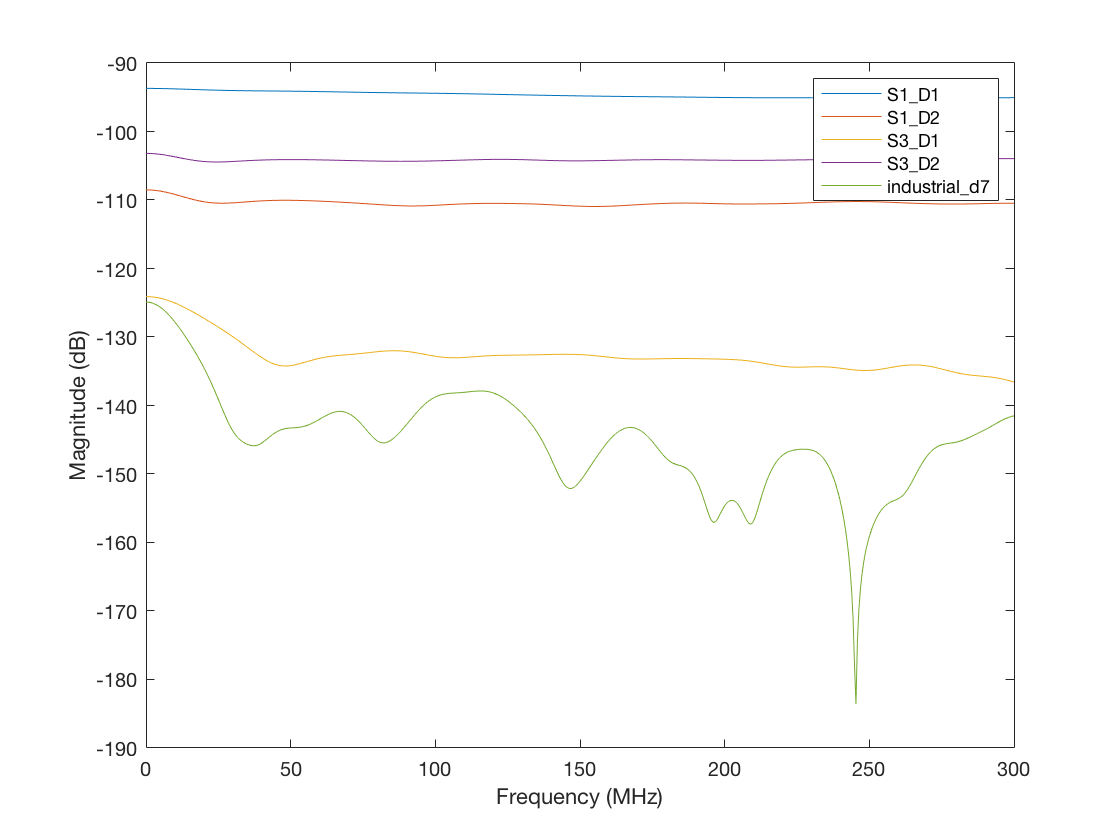

fs = 1e9;
figure
load('S1_D1.mat')
[H,f] = freqz(averun2,1,2001,'whole',fs);
plot(f/1e6,pow2db(abs(H).^2),'DisplayName','S1\_D1');
hold on;
load('S1_D2.mat')
[H,f] = freqz(averun2,1,2001,'whole',fs);
plot(f/1e6,pow2db(abs(H).^2),'DisplayName','S1\_D2');
load('S3_D1.mat')
[H,f] = freqz(averun2,1,2001,'whole',fs);
plot(f/1e6,pow2db(abs(H).^2),'DisplayName','S3\_D1');
load('S3_D2.mat')
[H,f] = freqz(averun2,1,2001,'whole',fs);
plot(f/1e6,pow2db(abs(H).^2),'DisplayName','S3\_D2');
load('industrial_d7.mat')
[H,f] = freqz(averun2,1,2001,'whole',fs);
plot(f/1e6,pow2db(abs(H).^2),'DisplayName','industrial\_d7');
legend -DynamicLegend
ylabel('Magnitude (dB)')
xlabel('Frequency (MHz)')
xlim([0,300])